% AP 7.14
clear all;
syms KP KD KI s w z f;
assume(KP,"real");
assume(KD,"real");
assume(KI,"real");
assume(w,"positive");

Gc = KP + KI/s + KD*s;
G = 10/(s*(s+10)*(s+7.5));

Ls_tem = subs(Gc*G,[KD KI],[0 0]); % KD, KI = 0
T_tem = simplify(Ls_tem/(1+Ls_tem));
[n, d] = numden(T_tem);

% 임계이득KP와 임계주기 Tu를 구하는 과정.
w = solve(imag(subs(d, s, 1i*w)) == 0, w);
f = solve(2*pi*f == w,f);
Tu = double(1/f)

Tu = 0.7255

Ku = double(solve(real(subs(d, s, 1i*w)) == 0, KP))

Ku = 131.2500


% KP = 0.6*Ku
% KI = 1.2*Ku/Tu
% KD = 0.6*Ku*Tu/8

% 단위계단응답
Ls = subs(Gc*G, [KP, KI, KD], [0.6*Ku, 1.2*Ku/Tu, 0.6*Ku*Tu/8]);
T_in = simplify(Ls/(1+Ls));
[n, d] = numden(T_in);
num = sym2poly(n);
den = sym2poly(d);
sys_in = tf(num, den)

sys_in =
 
                 4.02e16 s^2 + 4.433e17 s + 1.222e18
  ------------------------------------------------------------------
  5.629e14 s^4 + 9.852e15 s^3 + 8.243e16 s^2 + 4.433e17 s + 1.222e18
 
연속시간 전달 함수입니다.
모델 속성


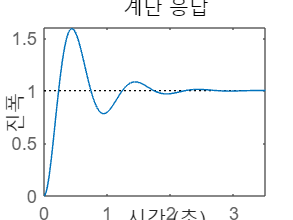

step(sys_in)


% 단위외란응답(step)
T_dis = simplify(subs(G/(1+Gc*G), [KP, KI, KD], [0.6*Ku, 1.2*Ku/Tu, 0.6*Ku*Tu/8]));
[n, d] = numden(T_dis);
num = sym2poly(n);
den = sym2poly(d);
sys_dis = tf(num, den)

sys_dis =
 
                              5.629e15 s
  ------------------------------------------------------------------
  5.629e14 s^4 + 9.852e15 s^3 + 8.243e16 s^2 + 4.433e17 s + 1.222e18
 
연속시간 전달 함수입니다.
모델 속성


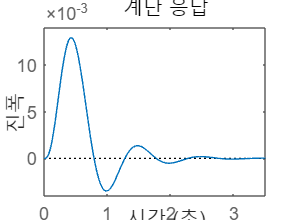

step(sys_dis)


% 단위계단입력에대한 백분율 오버슈트(PO)와 정착시간(Ts)
S = stepinfo(sys_in);
PO = S.Overshoot     % 단위[%]

PO = 58.8814

Ts = S.SettlingTime  % 단위[초]

Ts = 2.0845